## ---------------- ##

Definição de parâmetros

s = tf('s');

R1 = 10e+3;
C1 = 52e-9;
ZR1 = R1;
ZC1 = 1/(s*C1);

H_lpass = ZC1/(ZR1+ZC1)


H_lpass =
 
          5.2e-08 s
  -------------------------
  2.704e-11 s^2 + 5.2e-08 s
 
Continuous-time transfer function.
Model Properties


H_hpass = ZR1/(ZR1+ZC1)


H_hpass =
 
    0.00052 s
  -------------
  0.00052 s + 1
 
Continuous-time transfer function.
Model Properties



wc=1/(R1*C1)

w = 1.9231e+03

wc_hertz = wc/(2*pi)

freq_hertz = 306.0672

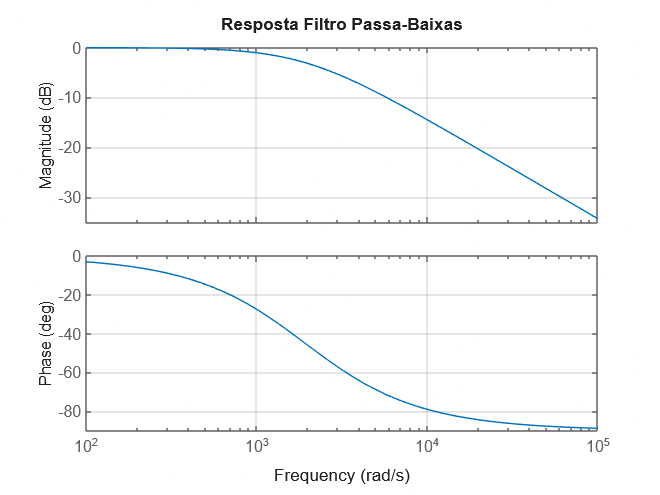


bode(H_lpass)
title('Resposta Filtro Passa-Baixas')
grid on

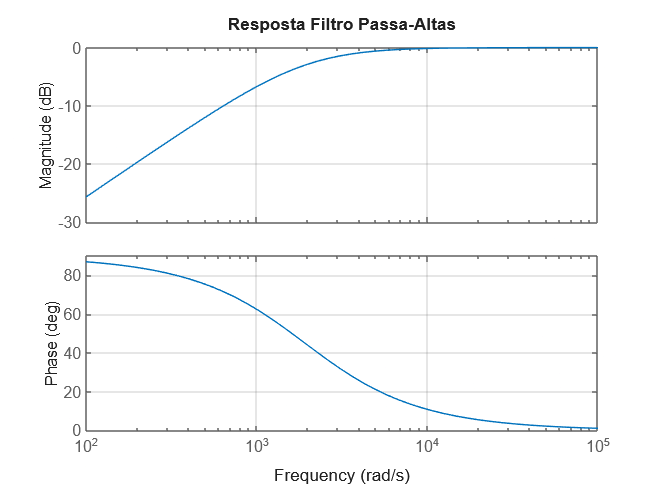


bode(H_hpass)
title('Resposta Filtro Passa-Altas')
grid on

## ---------------- ##

Questão 3

R1_bpass = 2000;
R2_bpass = 500;
C1_bpass = 1e-6;
C2_bpass = 0.1e-6;

% impedâncias
ZR1_bpass = R1_bpass;
ZC1_bpass = 1/(s*C1_bpass);
ZR2_bpass = R2_bpass;
ZC2_bpass = 1/(s*C2_bpass);

H1 = ZR1_bpass/(ZR1_bpass+ZC1_bpass)


H1 =
 
    0.002 s
  -----------
  0.002 s + 1
 
Continuous-time transfer function.
Model Properties


H2 = ZC2_bpass/(ZR2_bpass+ZC2_bpass)


H2 =
 
        1e-07 s
  -------------------
  5e-12 s^2 + 1e-07 s
 
Continuous-time transfer function.
Model Properties



w1_bpass = 1/(R1_bpass*C1_bpass)

w1_bpass = 500

w2_bpass = 1/(R2_bpass*C2_bpass)

w2_bpass = 20000

w1_hertz = w1_bpass/(2*pi)

w1_hertz = 79.5775

w2_hertz = w2_bpass/(2*pi)

w2_hertz = 3.1831e+03


wcenter = sqrt(w1_bpass*w2_bpass)

wcenter = 3.1623e+03

wcenter_hertz = wcenter/(2*pi)

wcenter_hertz = 503.2921


H_bpass = H1*H2 


H_bpass =
 
              2e-10 s^2
  ----------------------------------
  1e-14 s^3 + 2.05e-10 s^2 + 1e-07 s
 
Continuous-time transfer function.
Model Properties


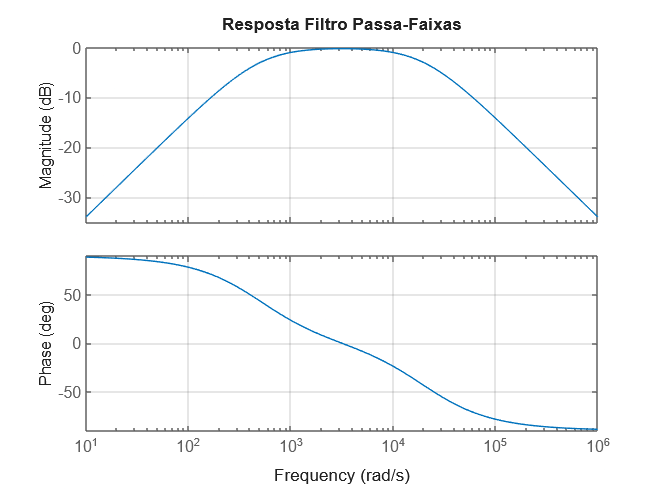


bode(H_bpass)
title('Resposta Filtro Passa-Faixas')
grid on